## Testing Nonlinear System Setup

% run the model with 2s simulation to get output array X of linear
% estimated states
% plot these for small starting pendulum angles and then also compare to linear model 

load('parameters.mat'); 
load('linear_system.mat')
parameters = p;
M = p.m + p.mp;
U = [M*p.g; 0; 0; 0];
mdl = 'drone';

alphas = [0 0.01 0.05 0.1];            % rad
figure; hold on
for a0 = alphas
    x0 = zeros(14,1); 
    x0(13) = a0;     % integrator IC uses x0
    out = sim(mdl, 'StopTime', '400');
    t = out.tout;  
    X = out.X;          % X is N x 14
    plot(t, rad2deg(X(:,13)), 'DisplayName', sprintf('\\alpha_0 = %.2f', a0));
end
xlabel('t (s)'); ylabel('\alpha (deg)'); legend; grid on

figure
subplot(4,1,1); plot(t, X(:,1:3));  ylabel('position (m)');   legend('x','y','z')
subplot(4,1,2); plot(t, X(:,7:9));  ylabel('attitude (rad)'); legend('\phi','\theta','\psi')
subplot(4,1,3); plot(t, X(:,13));   ylabel('\alpha (rad)')
subplot(4,1,4); plot(t, X(:,4:6));  ylabel('velocity (m/s)'); legend('xdot','ydot','zdot'); xlabel('t (s)')

x0 = zeros(14,1); 
x0(13) = 0.01;
out = sim(mdl, 'StopTime', '400');

tl = linspace(0, 400, 501)';                    
Xn = interp1(out.tout, out.X, tl);            
yl = initial(sys, x0, tl);                    

figure
plot(tl, Xn(:,13), tl, yl(:,13), '--')
legend('nonlinear','linear'); xlabel('t (s)'); ylabel('\alpha (rad)'); grid on

## Testing Eigenvalue Placement Controller

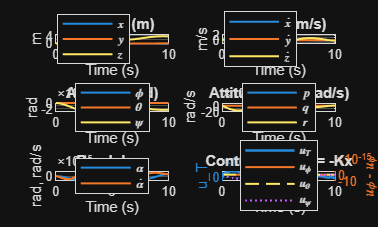

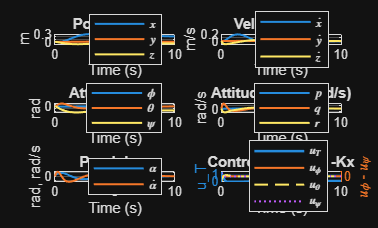

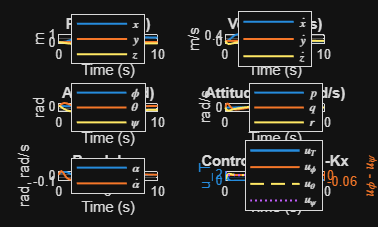

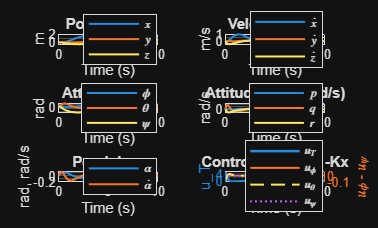

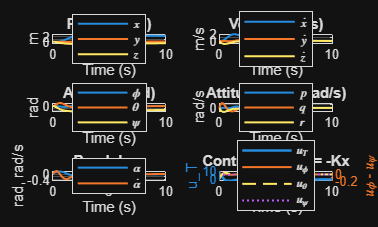

load('parameters.mat'); 
parameters = p;
M = p.m + p.mp;
U = [M*p.g; 0; 0; 0];
load('eigval_controller.mat');
mdl = 'eigval_drone';

alphas = [0 0.01 0.025 0.05 0.1];            % rad
fA = figure; axA = axes(fA); hold(axA,'on')
for a0 = alphas
    x0 = zeros(14,1); 
    x0(13) = a0;     % integrator IC uses x0
    out = sim(mdl, 'StopTime', '10');
    t = out.tout;  
    X = out.X;          % X is N x 14
    U_out = out.U;
    plot_lin_sys(t,X,U_out)
    plot(axA, t, rad2deg(X(:,13)), 'DisplayName', sprintf('\\alpha_0 = %.2f', a0));
end

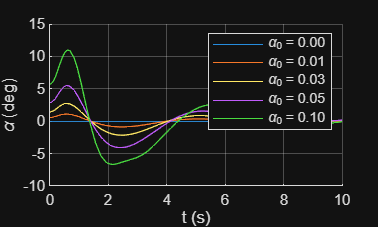

xlabel(axA,'t (s)'); ylabel(axA,'\alpha (deg)'); legend(axA); grid(axA,'on')

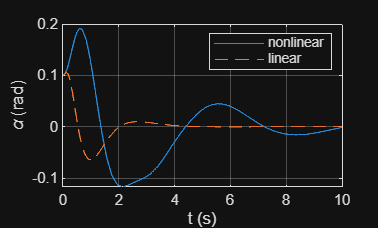


% Compare the nonlinear and linear closed-loop responses for the selected angle
tl = linspace(0, 10, 501)';
Xn = interp1(out.tout, out.X, tl);
syscl = ss(sys.A - sys.B*K, zeros(14,1), eye(14), 0);
yl = initial(syscl, x0, tl);
figure
plot(tl, Xn(:,13), tl, yl(:,13), '--')
legend('nonlinear','linear'); xlabel('t (s)'); ylabel('\alpha (rad)'); grid on